clc; clear;

% read image
image= imread('Y16.jpg');

bw = im2bw(image,0.60);

label = bwlabel(bw);
stats = regionprops(label, 'Solidity', 'Area');
density = [stats.Solidity];
area = [stats.Area];
denseArea = density > 0.25;
largestArea = max(area(denseArea));
tumorOutline = find(area == largestArea);
finalTumor = ismember(label, tumorOutline);
se = strel('diamond',5)

se = strel is a diamond shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


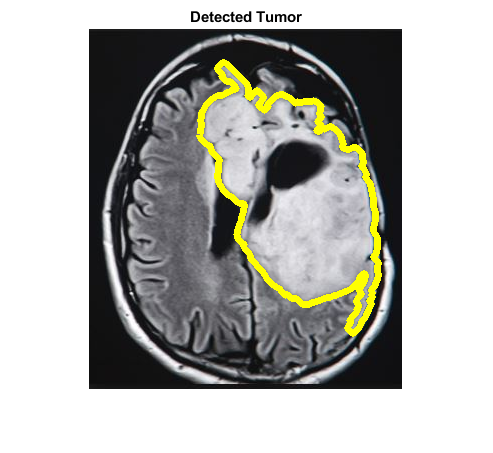

finalTumor = imdilate(finalTumor,se);

[B,L]= bwboundaries(finalTumor,'noholes');
imshow(image,[]);
hold on
for i = 1:length(B)
    plot(B{i}(:,2),B{i}(:,1),'y','linewidth',5);
end
title('Detected Tumor');
hold off